# Classical Astrodynamics with the Astrodynamics Toolbox

This script is intended to be converted into a MATLAB Live Script (.mlx). It provides an interactive overview of:

- classical orbital elements

- two-body motion and invariants

- Lambert transfers using the Izzo solver

- perturbed propagation with J2 and drag

- a JUICE-inspired MGA reconstruction and SPICE truth comparison

## Initialisation

clear; clc; close all;

## Paths and toolbox setup

scriptPath = matlab.desktop.editor.getActiveFilename;
scriptDir  = fileparts(scriptPath);
repoRoot   = fileparts(scriptDir);
kernelDir  = fullfile(repoRoot, 'data', 'spice');

run(fullfile(repoRoot, 'startup.m'));

astroToolbox path added.



miceLibDir = fullfile(repoRoot, 'external', 'mice', 'lib');
addpath(miceLibDir);
rehash;

assert(exist('mice', 'file') == 3, ...
    'MICE binary not found. Expected in: %s', miceLibDir);
assert(exist('cspice_kclear', 'file') == 2, ...
    'cspice_kclear not found on the MATLAB path.');

## Plot styling

A slightly cleaner and more colourful style for the live script figures.

clr.orbit    = [0.00 0.45 0.74];
clr.state    = [0.85 0.33 0.10];
clr.energy   = [0.49 0.18 0.56];
clr.pert     = [0.47 0.67 0.19];
clr.truth    = [0.00 0.60 0.30];
clr.recon    = [0.00 0.25 0.90];
clr.sun      = [0.95 0.70 0.10];
clr.body     = [0.20 0.20 0.20];

## Introduction

The two-body problem describes the motion of a spacecraft under the gravity of a central body of gravitational parameter $\mu$:


$$\ddot{\mathbf r} = -\mu \frac{\mathbf r}{r^3}$$


where $\mathbf r$ is the inertial position vector and $r=\|\mathbf r\|$. This idealised model neglects oblateness, atmospheric drag, solar radiation pressure, and third-body perturbations.

In the Keplerian approximation, the orbit is parameterised by the six classical orbital elements


$$a,\; e,\; i,\; \Omega,\; \omega,\; \nu$$


where:

- $a$ is the semi-major axis

- $e$ is the eccentricity

- $i$ is the inclination

- $\Omega$ is the right ascension of the ascending node

- $\omega$ is the argument of periapsis

- $\nu$ is the true anomaly

Their geometric meaning is as follows:

- $a$ controls the orbit size

- $e$ controls the orbit shape

- $i$ tilts the orbital plane relative to the reference plane

- $\Omega$ rotates the line of nodes in the reference plane

- $\omega$ rotates the periapsis direction inside the orbital plane

- $\nu$ locates the spacecraft on the conic

For an ellipse:


$$r_p = a(1-e), \qquad r_a = a(1+e)$$



$$T = 2\pi \sqrt{\frac{a^3}{\mu}}$$


In this toolbox:

- `astro.coords.coe2rv` maps orbital elements to Cartesian state

- `astro.coords.rv2coe` maps Cartesian state back to orbital elements

## User-defined orbital elements

mu = 398600.4418;   % Earth gravitational parameter [km^3/s^2]

a     = 53000;      % semi-major axis [km]
e     = 0.47;       % eccentricity [-]
inc   = 51;         % inclination [deg]
RAAN  = 40;         % right ascension of ascending node [deg]
omega = 60;         % argument of periapsis [deg]
nu    = 20;         % true anomaly [deg]

## Convert orbital elements to Cartesian state

[r0, v0] = astro.coords.coe2rv(a, e, inc, RAAN, omega, nu, mu);

disp('Initial position [km]:');

Initial position [km]:


disp(r0(:));

   1.0e+04 *

    2.1593
    1.4195
   -2.3080




disp('Initial velocity [km/s]:');

Initial velocity [km/s]:


disp(v0(:));

   -1.3976
    3.4907
   -1.1620



## Recover orbital elements from Cartesian state

coe_back = astro.coords.rv2coe(r0, v0, mu);

disp('Recovered orbital elements:');

Recovered orbital elements:


disp(coe_back);

        a: 5.3000e+04
        e: 0.4700
        i: 0.7345
     RAAN: 2.3009
    omega: 3.4513
    theta: 1.1504



## Characteristic orbital quantities

The specific angular momentum vector is


$$\mathbf h = \mathbf r \times \mathbf v$$


and the specific mechanical energy is


$$\varepsilon = \frac{v^2}{2} - \frac{\mu}{r}$$


For a perfect Keplerian ellipse,


$$\varepsilon = -\frac{\mu}{2a}$$


The toolbox already contains dedicated utilities for these quantities.

h_vec  = astro.utils.angularMomentum(r0, v0);
h      = norm(h_vec);
rp     = a*(1 - e);
ra     = a*(1 + e);
T      = astro.maneuvers.orbitalPeriod(a, mu);
energy = astro.utils.specificEnergy(r0, v0, mu);

fprintf('Specific angular momentum h = %.6f km^2/s\n', h);

Specific angular momentum h = 128293.137084 km^2/s


fprintf('Periapsis radius rp         = %.6f km\n', rp);

Periapsis radius rp         = 28090.000000 km


fprintf('Apoapsis radius ra          = %.6f km\n', ra);

Apoapsis radius ra          = 77910.000000 km


fprintf('Orbital period T            = %.6f s\n', T);

Orbital period T            = 121429.661647 s


fprintf('Specific energy eps         = %.6f km^2/s^2\n', energy);

Specific energy eps         = -3.760382 km^2/s^2


## Quick orbit visualisation

To visualise the orbit, we propagate the initial state for one orbital period using the existing two-body equations of motion:


$$\dot{\mathbf{x}} =
\left[
\begin{array}{c}
\mathbf{v} \\
-\mu \mathbf{r}/r^3
\end{array}
\right],
\qquad
\mathbf{x} =
\left[
\begin{array}{c}
\mathbf{r} \\
\mathbf{v}
\end{array}
\right]$$


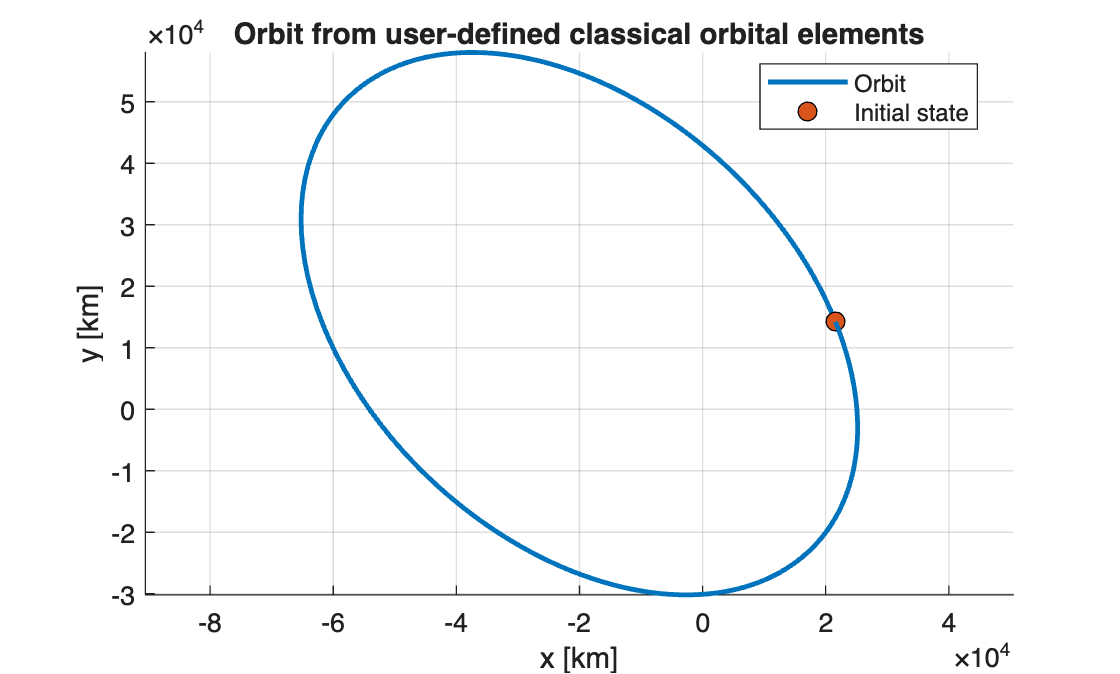

x0 = [r0(:); v0(:)];
dynTwoBody = @(t, x) astro.propagators.eomTwoBody(t, x, mu);

out_orbit = astro.propagators.propagate(dynTwoBody, [0 T], x0);

figure('Color','w');
hold on; grid on; axis equal;
astro.plot.plotOrbit3D(out_orbit.x(:,1:3), 'Color', clr.orbit, 'LineWidth', 1.8);
plot3(r0(1), r0(2), r0(3), 'o', ...
    'MarkerSize', 7, 'MarkerFaceColor', clr.state, 'MarkerEdgeColor', 'k');
xlabel('x [km]');
ylabel('y [km]');
zlabel('z [km]');
title('Orbit from user-defined classical orbital elements');
legend('Orbit', 'Initial state', 'Location', 'best');

## Two-dimensional projection

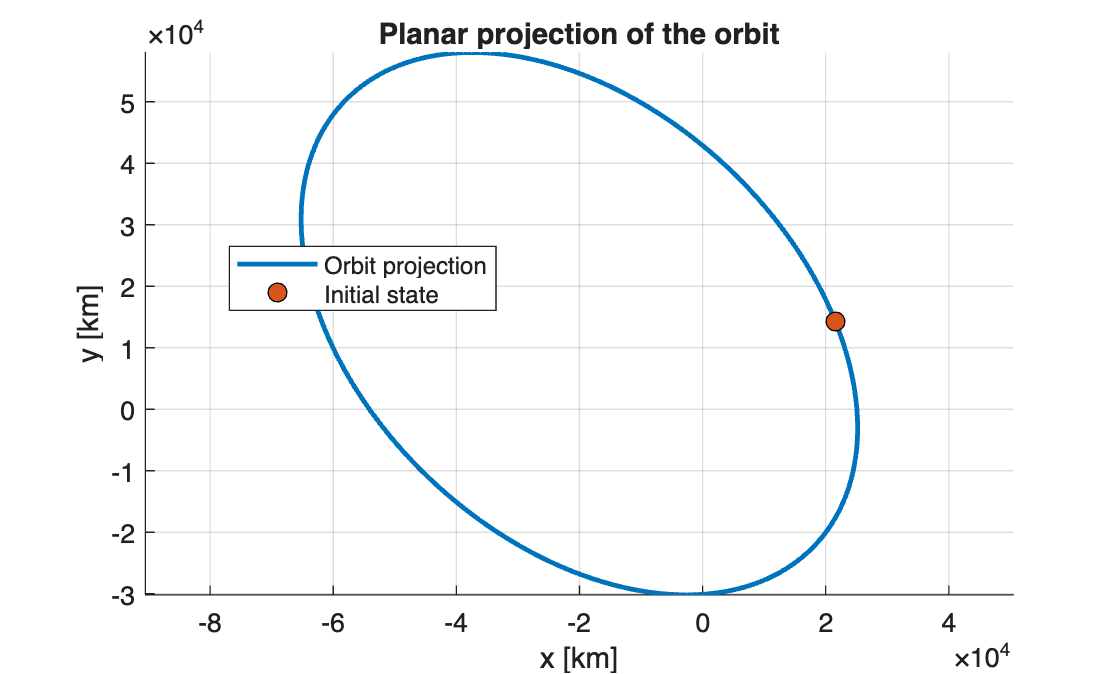

figure('Color','w');
hold on; grid on; axis equal;
astro.plot.plotOrbit2D(out_orbit.x(:,1:3), 'Color', clr.orbit, 'LineWidth', 1.8);
plot(r0(1), r0(2), 'o', ...
    'MarkerSize', 7, 'MarkerFaceColor', clr.state, 'MarkerEdgeColor', 'k');
xlabel('x [km]');
ylabel('y [km]');
title('Planar projection of the orbit');
legend('Orbit projection', 'Initial state', 'Location', 'best');

## Two-body propagation over 1.5 periods

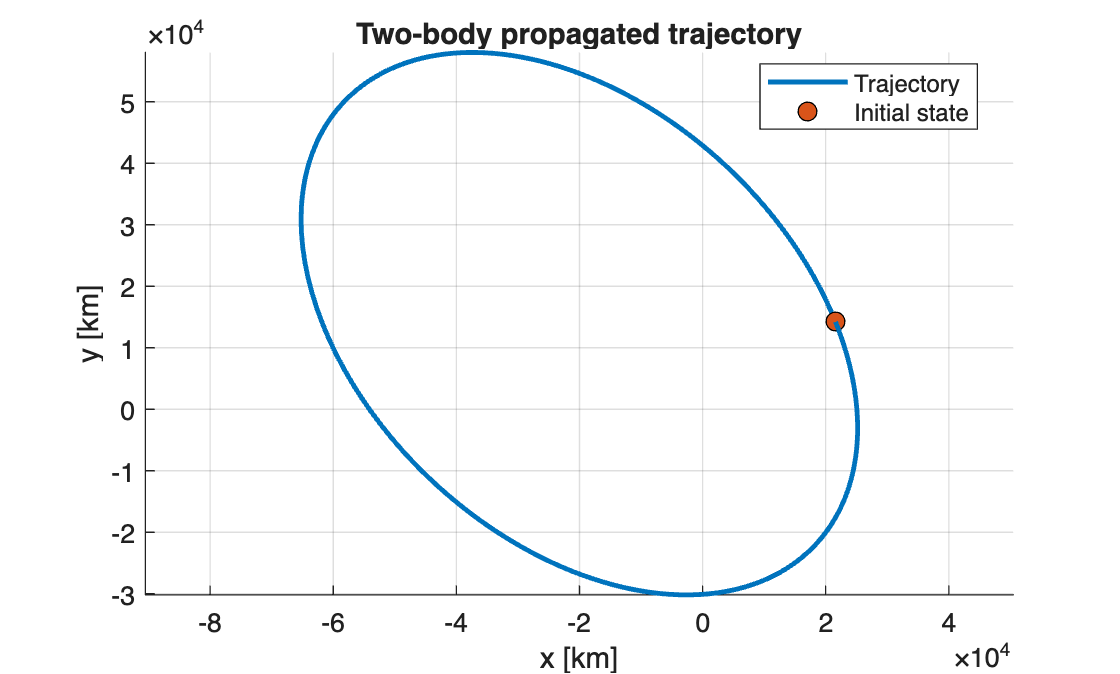

tf = 1.5*T;
out2b = astro.propagators.propagate(dynTwoBody, [0 tf], x0);

figure('Color','w');
hold on; grid on; axis equal;
astro.plot.plotOrbit3D(out2b.x(:,1:3), 'Color', clr.orbit, 'LineWidth', 1.8);
plot3(r0(1), r0(2), r0(3), 'o', ...
    'MarkerSize', 7, 'MarkerFaceColor', clr.state, 'MarkerEdgeColor', 'k');
xlabel('x [km]');
ylabel('y [km]');
zlabel('z [km]');
title('Two-body propagated trajectory');
legend('Trajectory', 'Initial state', 'Location', 'best');

## Radius, speed, and specific energy histories

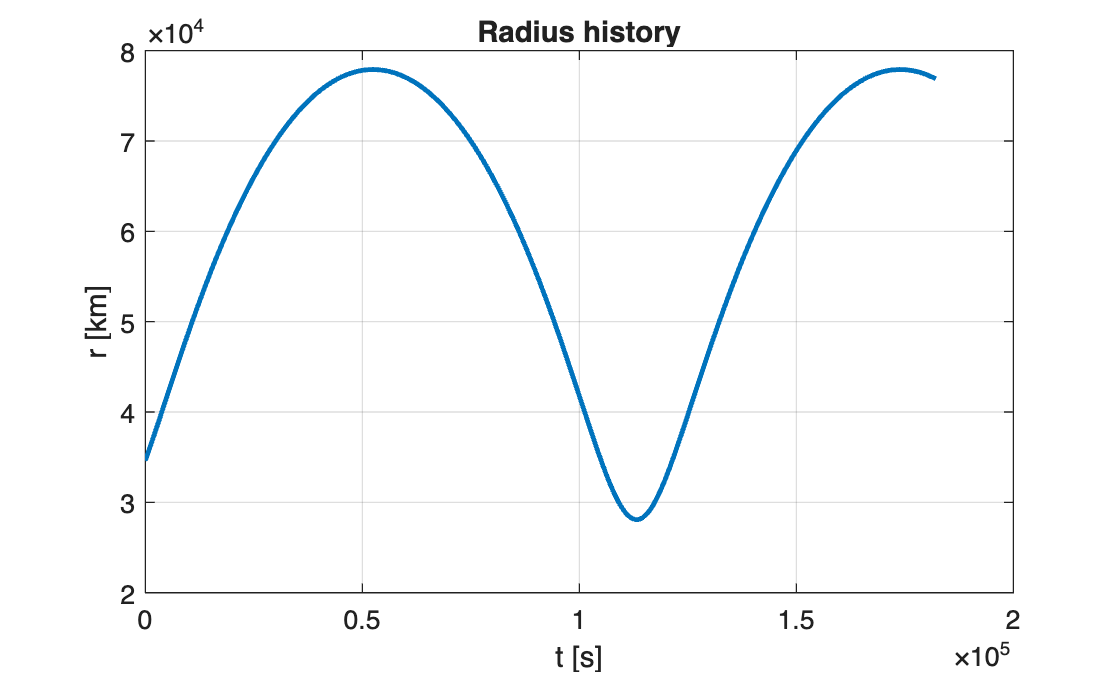

r_norm = vecnorm(out2b.x(:,1:3), 2, 2);
v_norm = vecnorm(out2b.x(:,4:6), 2, 2);

energy_hist = zeros(length(out2b.t), 1);
h_hist      = zeros(length(out2b.t), 1);

for k = 1:length(out2b.t)
    rk = out2b.x(k,1:3).';
    vk = out2b.x(k,4:6).';
    energy_hist(k) = astro.utils.specificEnergy(rk, vk, mu);
    h_hist(k)      = norm(astro.utils.angularMomentum(rk, vk));
end

figure('Color','w');
plot(out2b.t, r_norm, 'Color', clr.orbit, 'LineWidth', 1.8);
grid on;
xlabel('t [s]');
ylabel('r [km]');
title('Radius history');

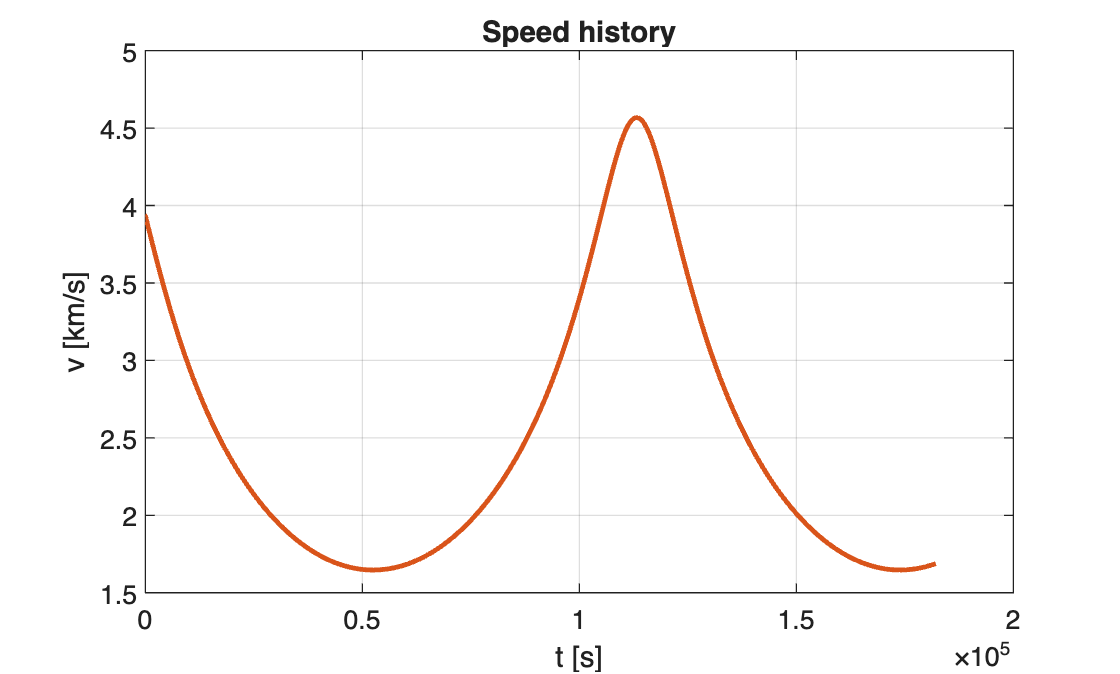


figure('Color','w');
plot(out2b.t, v_norm, 'Color', clr.state, 'LineWidth', 1.8);
grid on;
xlabel('t [s]');
ylabel('v [km/s]');
title('Speed history');

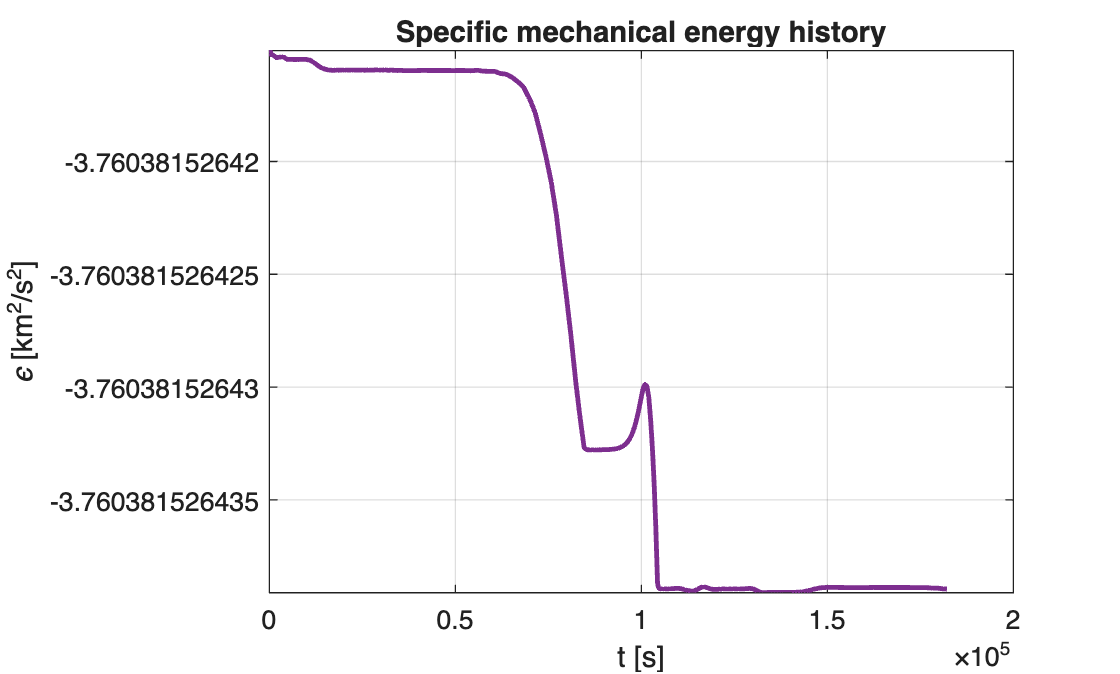


figure('Color','w');
plot(out2b.t, energy_hist, 'Color', clr.energy, 'LineWidth', 1.8);
grid on;
xlabel('t [s]');
ylabel('\epsilon [km^2/s^2]');
title('Specific mechanical energy history');

## Invariant checks

In the ideal two-body problem, both $\mathbf h$ and $\varepsilon$ should remain constant up to numerical integration error.

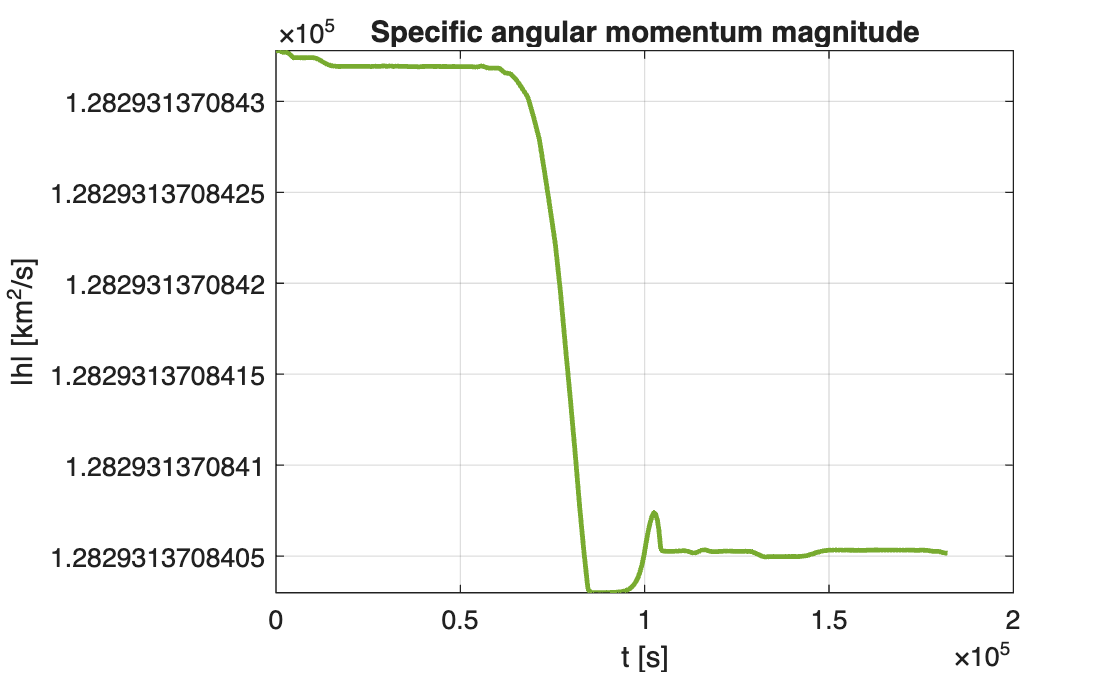

figure('Color','w');
plot(out2b.t, h_hist, 'Color', clr.pert, 'LineWidth', 1.8);
grid on;
xlabel('t [s]');
ylabel('|h| [km^2/s]');
title('Specific angular momentum magnitude');

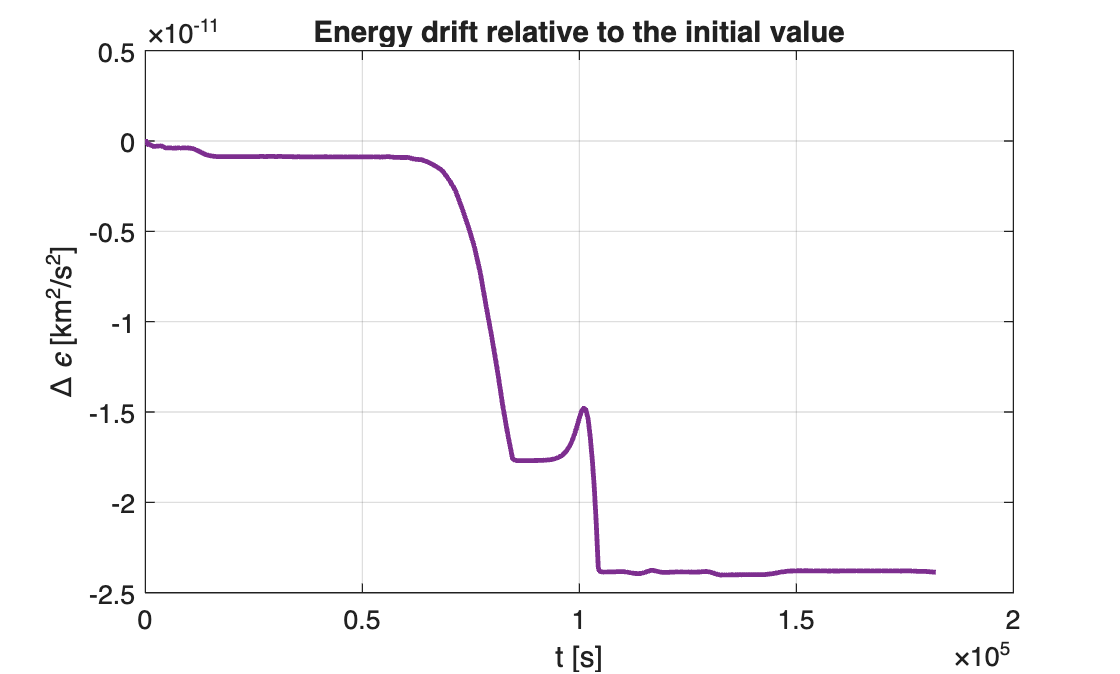


figure('Color','w');
plot(out2b.t, energy_hist - energy_hist(1), 'Color', clr.energy, 'LineWidth', 1.8);
grid on;
xlabel('t [s]');
ylabel('\Delta \epsilon [km^2/s^2]');
title('Energy drift relative to the initial value');

## Lambert problem overview

The Lambert problem seeks an orbit connecting two position vectors in a prescribed time of flight:


$$\mathbf r_1,\; \mathbf r_2,\; \Delta t,\; \mu
 \quad \longrightarrow \quad
 \mathbf v_1,\; \mathbf v_2$$


The implementation in this toolbox follows the Izzo-style formulation and returns a structure containing the transfer velocities and iteration data.

## Geometric parameters in Izzo's formulation

Let


$$r_1 = \|\mathbf r_1\|, \qquad r_2 = \|\mathbf r_2\|$$


and define the chord


$$c = \|\mathbf r_2 - \mathbf r_1\|$$


and the semiperimeter


$$s = \frac{1}{2}(r_1 + r_2 + c)$$


A fundamental nondimensional geometry parameter is


$$\lambda = \pm \sqrt{1 - \frac{c}{s}}$$


whose sign distinguishes the transfer branch and depends on the selected short-way or long-way solution.

The nondimensional time of flight is


$$T^\star = \sqrt{\frac{2\mu}{s^3}}\,\Delta t$$


The solver searches for a scalar parameter $x$ that satisfies the nondimensional time-of-flight equation. Once $x$ is determined, the auxiliary variable $y$ is computed and the departure and arrival velocities are reconstructed from radial and transverse components.

In the current implementation:

- `lambda` captures the transfer geometry

- `x` is the Householder iteration variable

- `y` is the associated auxiliary parameter

- `tofError` is the residual mismatch in nondimensional time of flight

The solver also exposes the iteration count and convergence flag.

## Basic Lambert example

r1 = [7000; 0; 0];
r2 = [8000; 9000; 0];
dt = 3600;
longWay = false;

sol_izzo = astro.lambert.solveIzzo(r1, r2, dt, mu, longWay);

v1_izzo = sol_izzo.v1;
v2_izzo = sol_izzo.v2;

disp('Izzo departure velocity [km/s]:');

Izzo departure velocity [km/s]:


disp(v1_izzo(:));

    6.3610
    4.3506
         0




disp('Izzo arrival velocity [km/s]:');

Izzo arrival velocity [km/s]:


disp(v2_izzo(:));

   -3.4215
   -0.0424
         0




fprintf('Izzo converged     = %d\n', sol_izzo.converged);

Izzo converged     = 1


fprintf('Izzo iterations    = %d\n', sol_izzo.iterations);

Izzo iterations    = 3


fprintf('Izzo TOF error     = %.6e\n', sol_izzo.tofError);

Izzo TOF error     = -2.220446e-16


fprintf('Izzo lambda        = %.6f\n', sol_izzo.lambda);

Izzo lambda        = 0.596171


fprintf('Izzo x parameter   = %.6f\n', sol_izzo.x);

Izzo x parameter   = -0.199153


fprintf('Izzo y parameter   = %.6f\n', sol_izzo.y);

Izzo y parameter   = 0.811589


## Lambert transfer arc visualisation

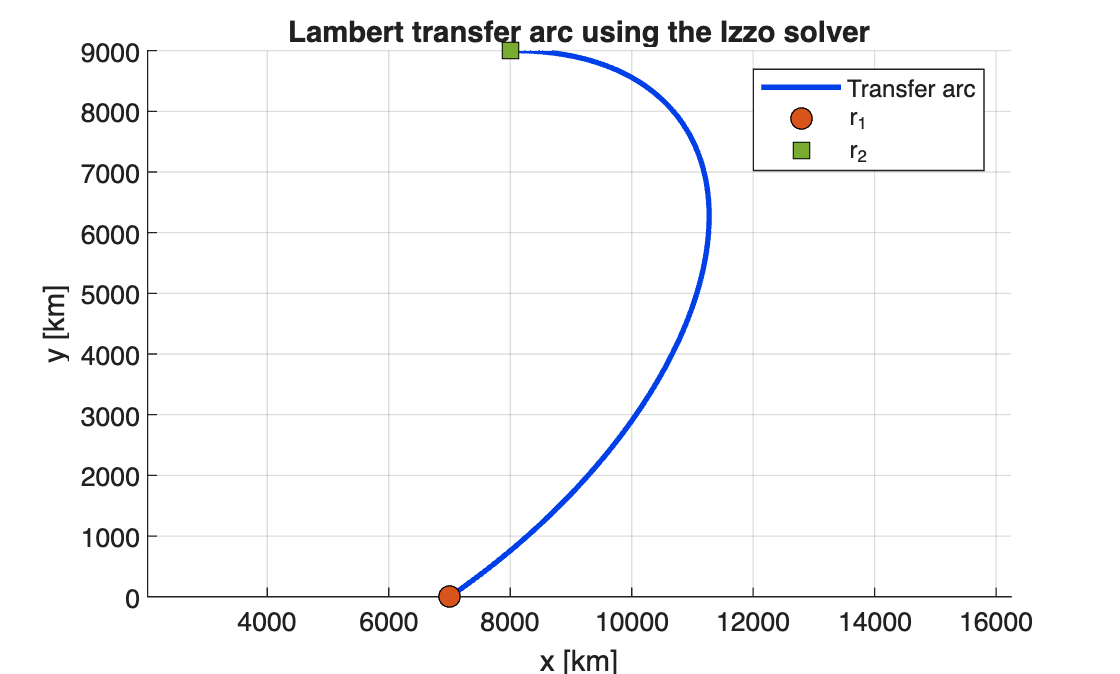

xLam0 = [r1; v1_izzo];
outLam = astro.propagators.propagate(dynTwoBody, [0 dt], xLam0);

figure('Color','w');
hold on; grid on; axis equal;
astro.plot.plotOrbit2D(outLam.x(:,1:3), 'Color', clr.recon, 'LineWidth', 2.0);
plot(r1(1), r1(2), 'o', ...
    'MarkerSize', 8, 'MarkerFaceColor', clr.state, 'MarkerEdgeColor', 'k');
plot(r2(1), r2(2), 's', ...
    'MarkerSize', 8, 'MarkerFaceColor', clr.pert, 'MarkerEdgeColor', 'k');
xlabel('x [km]');
ylabel('y [km]');
title('Lambert transfer arc using the Izzo solver');
legend('Transfer arc', 'r_1', 'r_2', 'Location', 'best');

## Lambert endpoint check

r2_prop = outLam.x(end,1:3).';
endpoint_error = norm(r2_prop - r2);

disp('Propagated final position [km]:');

Propagated final position [km]:


disp(r2_prop);

   1.0e+03 *

    8.0000
    9.0000
         0




fprintf('Lambert endpoint position error = %.6e km\n', endpoint_error);

Lambert endpoint position error = 3.895059e-10 km


## Perturbed propagation overview

In Cowell form, perturbations are added directly to the inertial acceleration:


$$\ddot{\mathbf r} = -\mu \frac{\mathbf r}{r^3} + \mathbf a_{pert}$$


In this example, the perturbing acceleration includes J2 and drag.

## J2 perturbation model

The largest correction to the point-mass Earth gravity field is due to the oblateness coefficient $J_2$. A standard Cartesian expression is


$$\mathbf a_{J_2}
 = \frac{3J_2 \mu R^2}{2r^5}
 \begin{bmatrix}
 x\left(5\frac{z^2}{r^2} - 1\right) \\
 y\left(5\frac{z^2}{r^2} - 1\right) \\
 z\left(5\frac{z^2}{r^2} - 3\right)
 \end{bmatrix}$$


where $R$ is the equatorial radius of the central body.

This perturbation generates secular precession of the node and argument of periapsis, especially for LEO and MEO trajectories.

## Atmospheric drag model

A simple drag model writes


$$\mathbf a_{drag}
 = -\frac{1}{2}\rho C_D \frac{A}{m} \|\mathbf v_{rel}\|\,\mathbf v_{rel}$$


where:

- $\rho$ is atmospheric density

- $C_D$ is the drag coefficient

- $A/m$ is the area-to-mass ratio

- $\mathbf v_{rel}$ is the velocity relative to the rotating atmosphere

An exponential density profile is often used:


$$\rho(h) = \rho_0 \exp\!\left(-\frac{h-h_0}{H}\right)$$


with $H$ the scale height.

In the toolbox, these terms are handled through the existing perturbation models called by `astro.propagators.eomCowell`.

## J2 and drag propagation example

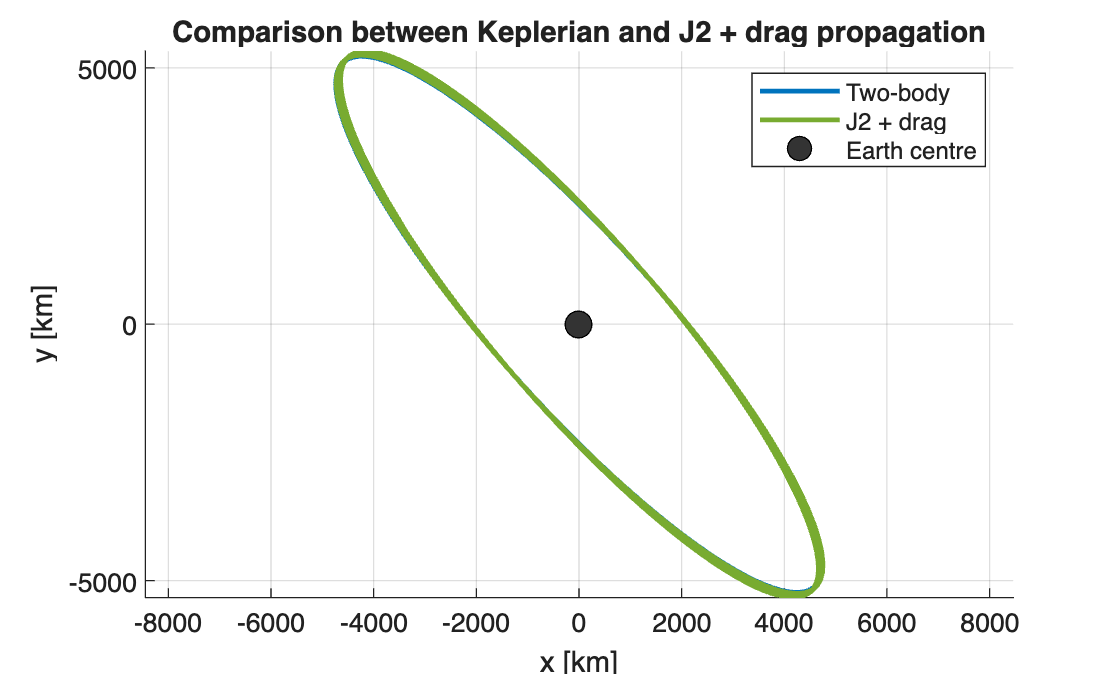

earth = astro.bodies.getBody('earth');

a_pert     = earth.radius + 500;   % km
e_pert     = 0.001;
inc_pert   = 51.6;                 % deg
RAAN_pert  = 40;                   % deg
omega_pert = 20;                   % deg
theta_pert = 0;                    % deg

[r0p, v0p] = astro.coords.coe2rv( ...
    a_pert, e_pert, inc_pert, RAAN_pert, omega_pert, theta_pert, earth.mu);

x0p = [r0p; v0p];

pert = struct();
pert.useJ2     = true;
pert.useDrag   = true;
pert.Cd        = 2.2;
pert.AoverM    = 0.01;          % m^2/kg
pert.rho0      = 3.614e-13;     % kg/m^3
pert.H         = 88.667;        % km
pert.omegaBody = 7.2921159e-5;  % rad/s

Torb_pert  = astro.maneuvers.orbitalPeriod(a_pert, earth.mu);
tspan_pert = [0, 10*Torb_pert];

optsPert = struct();
optsPert.RelTol = 1e-11;
optsPert.AbsTol = 1e-11;
optsPert.Solver = 'ode113';

outKepler = astro.propagators.propagate( ...
    @(t,x) astro.propagators.eomTwoBody(t, x, earth.mu), ...
    tspan_pert, x0p, optsPert);

outPert = astro.propagators.propagate( ...
    @(t,x) astro.propagators.eomCowell(t, x, earth, pert), ...
    tspan_pert, x0p, optsPert);

figure('Color','w');
hold on; grid on; axis equal;
astro.plot.plotOrbit2D(outKepler.x(:,1:3), 'Color', clr.orbit, 'LineWidth', 1.8);
astro.plot.plotOrbit2D(outPert.x(:,1:3),   'Color', clr.pert,  'LineWidth', 1.8);
plot(0, 0, 'o', 'MarkerSize', 10, 'MarkerFaceColor', clr.body, 'MarkerEdgeColor', 'k');
xlabel('x [km]');
ylabel('y [km]');
title('Comparison between Keplerian and J2 + drag propagation');
legend('Two-body', 'J2 + drag', 'Earth centre', 'Location', 'best');

## Separation growth due to perturbations

Because adaptive integration returns different time grids for the two trajectories, both solutions are interpolated to a common time vector before subtraction.

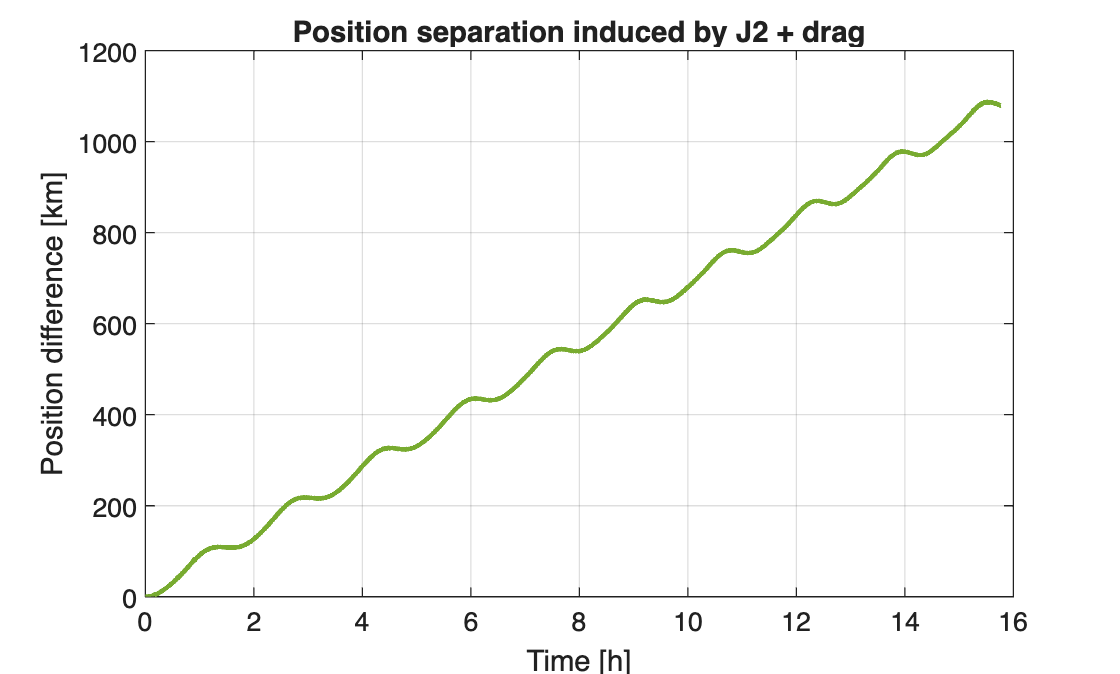

tCommon = linspace(0, tspan_pert(end), 2000).';

rKepler = interp1(outKepler.t, outKepler.x(:,1:3), tCommon, 'pchip');
rPert   = interp1(outPert.t,   outPert.x(:,1:3),   tCommon, 'pchip');

dr_pert  = rPert - rKepler;
sep_pert = vecnorm(dr_pert, 2, 2);

figure('Color','w');
plot(tCommon/3600, sep_pert, 'Color', clr.pert, 'LineWidth', 1.8);
grid on;
xlabel('Time [h]');
ylabel('Position difference [km]');
title('Position separation induced by J2 + drag');

## Velocity separation due to perturbations

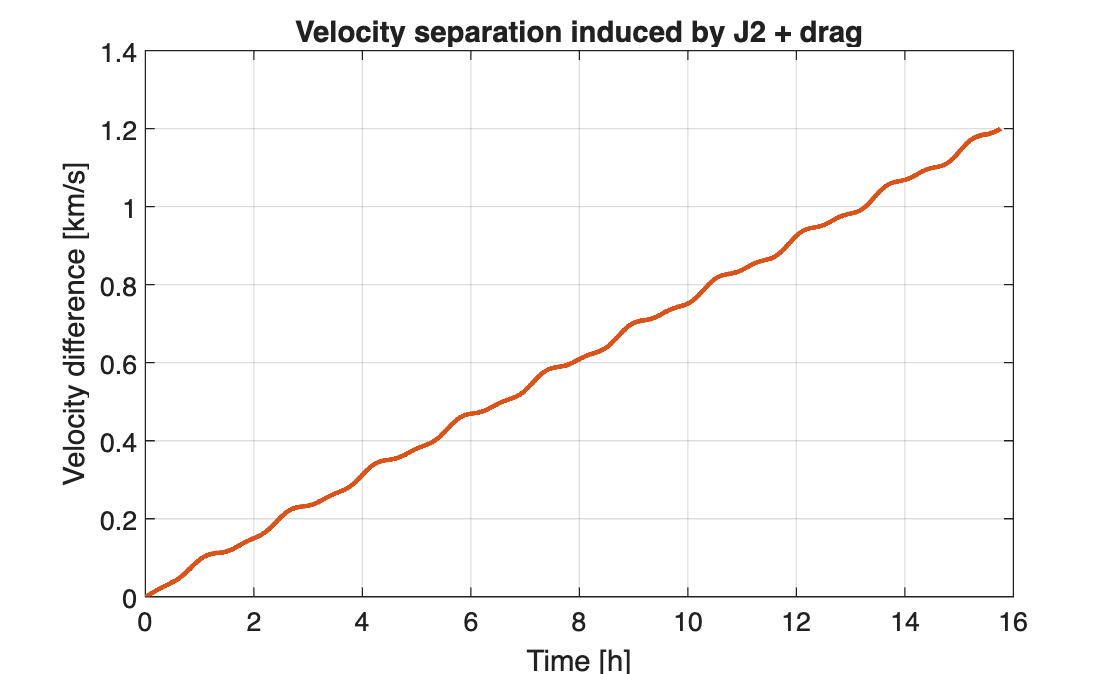

vKepler = interp1(outKepler.t, outKepler.x(:,4:6), tCommon, 'pchip');
vPert   = interp1(outPert.t,   outPert.x(:,4:6),   tCommon, 'pchip');

dv_pert   = vPert - vKepler;
speed_sep = vecnorm(dv_pert, 2, 2);

figure('Color','w');
plot(tCommon/3600, speed_sep, 'Color', clr.state, 'LineWidth', 1.8);
grid on;
xlabel('Time [h]');
ylabel('Velocity difference [km/s]');
title('Velocity separation induced by J2 + drag');

## Element drift under perturbations

This section converts the perturbed Cartesian state back to orbital elements in order to visualise secular drift.

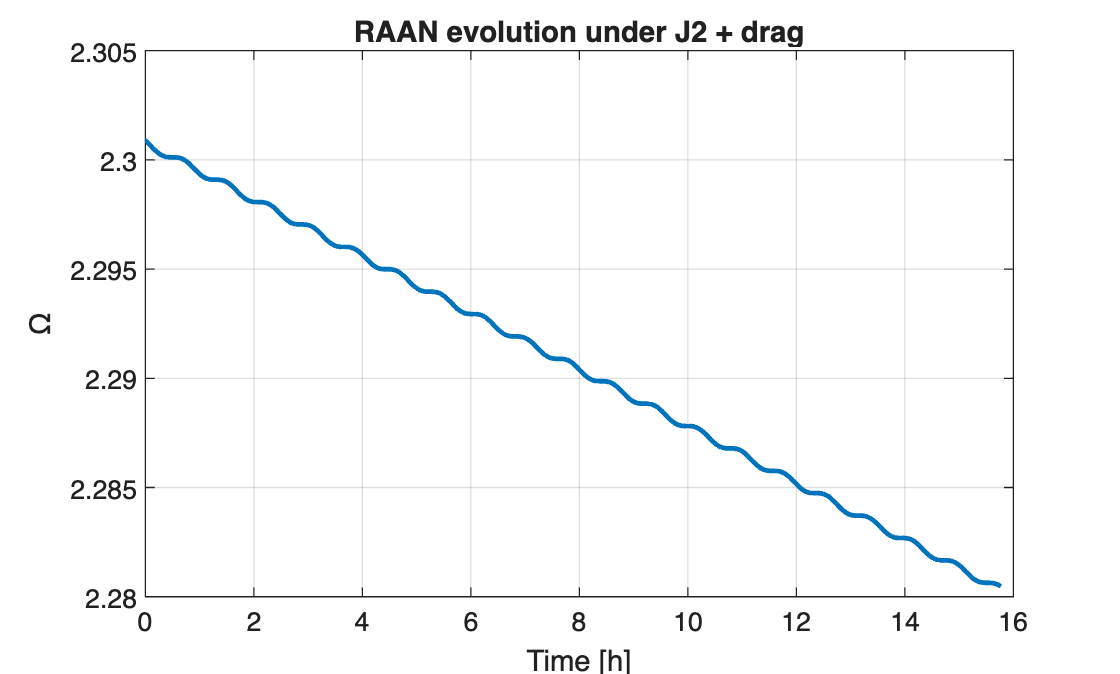

nPert = length(outPert.t);
a_hist     = zeros(nPert,1);
e_hist     = zeros(nPert,1);
inc_hist   = zeros(nPert,1);
RAAN_hist  = zeros(nPert,1);
omega_hist = zeros(nPert,1);

for k = 1:nPert
    coe_k = astro.coords.rv2coe(outPert.x(k,1:3).', outPert.x(k,4:6).', earth.mu);
    a_hist(k)     = coe_k.a;
    e_hist(k)     = coe_k.e;
    inc_hist(k)   = coe_k.i;
    RAAN_hist(k)  = coe_k.RAAN;
    omega_hist(k) = coe_k.omega;
end

figure('Color','w');
plot(outPert.t/3600, RAAN_hist, 'Color', clr.orbit, 'LineWidth', 1.8);
grid on;
xlabel('Time [h]');
ylabel('\Omega');
title('RAAN evolution under J2 + drag');

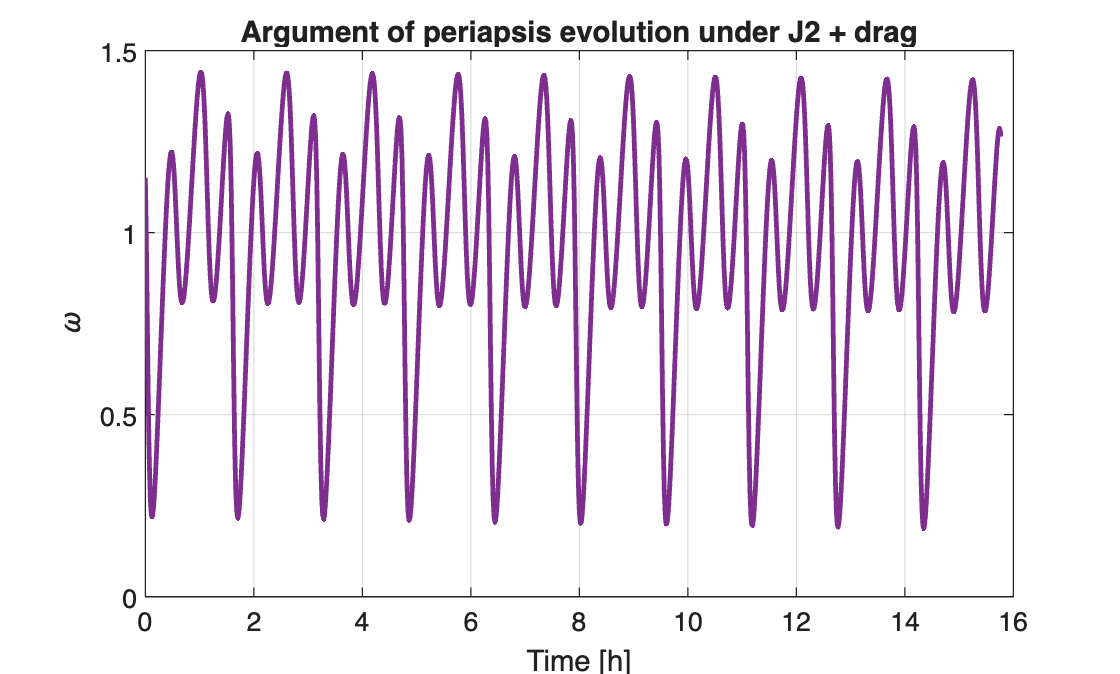


figure('Color','w');
plot(outPert.t/3600, omega_hist, 'Color', clr.energy, 'LineWidth', 1.8);
grid on;
xlabel('Time [h]');
ylabel('\omega');
title('Argument of periapsis evolution under J2 + drag');

## JUICE-inspired MGA reconstruction and SPICE comparison

This section mirrors the logic of the validation workflow already built in the repository:

1. define a heliocentric encounter sequence 2. build the Lambert/MGA reconstruction 3. evaluate the flyby feasibility 4. plot the reconstructed heliocentric trajectory 5. compare against JUICE SPICE truth if the mission kernels are available

## Load SPICE kernels

astro.ephem.loadSpiceKernels(kernelDir);

Loaded SPICE kernels from:
  /Users/gianlucamolinari/Desktop/astroToolbox/data/spice
  TLS loaded : /Users/gianlucamolinari/Desktop/astroToolbox/data/spice/naif0012.tls
  BSP count  : 91
  FK count   : 50
  PCK count  : 25
  CK count   : 142
  SCLK count : 9



sun     = astro.bodies.getBody('sun');
earth   = astro.bodies.getBody('earth');
venus   = astro.bodies.getBody('venus');
jupiter = astro.bodies.getBody('jupiter');

## Heliocentric sequence and encounter dates

sequence = {'earth','earth','venus','earth','earth','jupiter'};
dates = {
    '2023-04-14 12:14:00'
    '2024-08-20 21:56:00'
    '2025-08-31 00:00:00'
    '2026-09-01 00:00:00'
    '2029-01-01 00:00:00'
    '2031-07-01 00:00:00'};

planetNames = {'Earth','Earth (LEGA)','Venus','Earth','Earth','Jupiter'};

fprintf('\n============================================================\n');

fprintf('JUICE Reference Trajectory Reconstruction & Analysis\n');

JUICE Reference Trajectory Reconstruction & Analysis


fprintf('============================================================\n');

fprintf('\nEncounter epochs used:\n');


Encounter epochs used:


for k = 1:numel(sequence)
    fprintf('  %-8s : %s\n', upper(sequence{k}), dates{k});
end

  EARTH    : 2023-04-14 12:14:00
  EARTH    : 2024-08-20 21:56:00
  VENUS    : 2025-08-31 00:00:00
  EARTH    : 2026-09-01 00:00:00
  EARTH    : 2029-01-01 00:00:00
  JUPITER  : 2031-07-01 00:00:00


fprintf('\nNote: the 2024 lunar-Earth gravity assist is represented here\n');


Note: the 2024 lunar-Earth gravity assist is represented here


fprintf('as a single Earth-system flyby in the heliocentric chain.\n');

as a single Earth-system flyby in the heliocentric chain.


## Build the MGA trajectory

traj = astro.mga.propagateMGA(sequence, dates, sun.mu, 'spice');

## Flyby feasibility analysis

bodyMap = struct();
bodyMap.earth = earth;
bodyMap.venus = venus;

minAltMap = struct();
minAltMap.earth = 300;   % km
minAltMap.venus = 300;   % km

report = astro.mga.evaluateMGA(traj, bodyMap, minAltMap, 1e-3);

fprintf('\nLeg summary:\n');


Leg summary:


for k = 1:numel(traj.legs)
    fprintf('\nLeg %d: %s -> %s\n', ...
        k, upper(traj.legs(k).bodyDepart), upper(traj.legs(k).bodyArrive));
    fprintf('  TOF                 : %.2f days\n', traj.legs(k).tofDays);
    fprintf('  |v_inf,dep|         : %.6f km/s\n', traj.legs(k).vInfDepMag);
    fprintf('  |v_inf,arr|         : %.6f km/s\n', traj.legs(k).vInfArrMag);
end


Leg 1: EARTH -> EARTH


  TOF                 : 494.40 days


  |v_inf,dep|         : 23.336103 km/s


  |v_inf,arr|         : 23.348892 km/s



Leg 2: EARTH -> VENUS


  TOF                 : 375.09 days


  |v_inf,dep|         : 25.736951 km/s


  |v_inf,arr|         : 30.030357 km/s



Leg 3: VENUS -> EARTH


  TOF                 : 366.00 days


  |v_inf,dep|         : 6.275014 km/s


  |v_inf,arr|         : 10.367621 km/s



Leg 4: EARTH -> EARTH


  TOF                 : 853.00 days


  |v_inf,dep|         : 28.817729 km/s


  |v_inf,arr|         : 28.766358 km/s



Leg 5: EARTH -> JUPITER


  TOF                 : 911.00 days


  |v_inf,dep|         : 9.181016 km/s


  |v_inf,arr|         : 5.910941 km/s



fprintf('\nFlyby diagnostic summary:\n');


Flyby diagnostic summary:


for k = 1:report.nFlybys
    fb  = report.flybys(k);
    chk = fb.check;
    fprintf('\nFlyby at %s\n', upper(fb.body));
    fprintf('  Incoming |v_inf^-|       : %.6f km/s\n', chk.magIn);
    fprintf('  Required |v_inf^+|       : %.6f km/s\n', chk.magOutReq);
    fprintf('  Magnitude mismatch       : %.6f km/s\n', chk.magMismatch);
    fprintf('  Required turn angle      : %.6f deg\n', chk.deltaReqDeg);
    fprintf('  Max turn angle @ rpMin   : %.6f deg\n', chk.deltaMaxDeg);
    fprintf('  Feasible (ballistic)     : %d\n', chk.feasible);
end


Flyby at EARTH


  Incoming |v_inf^-|       : 23.348892 km/s


  Required |v_inf^+|       : 25.736951 km/s


  Magnitude mismatch       : 2.388059 km/s


  Required turn angle      : 33.774123 deg


  Max turn angle @ rpMin   : 11.326324 deg


  Feasible (ballistic)     : 0



Flyby at VENUS


  Incoming |v_inf^-|       : 30.030357 km/s


  Required |v_inf^+|       : 6.275014 km/s


  Magnitude mismatch       : 23.755343 km/s


  Required turn angle      : 68.413298 deg


  Max turn angle @ rpMin   : 6.152918 deg


  Feasible (ballistic)     : 0



Flyby at EARTH


  Incoming |v_inf^-|       : 10.367621 km/s


  Required |v_inf^+|       : 28.817729 km/s


  Magnitude mismatch       : 18.450108 km/s


  Required turn angle      : 15.196385 deg


  Max turn angle @ rpMin   : 41.836486 deg


  Feasible (ballistic)     : 0



Flyby at EARTH


  Incoming |v_inf^-|       : 28.766358 km/s


  Required |v_inf^+|       : 9.181016 km/s


  Magnitude mismatch       : 19.585342 km/s


  Required turn angle      : 56.589090 deg


  Max turn angle @ rpMin   : 7.715184 deg


  Feasible (ballistic)     : 0



launchC3 = astro.maneuvers.C3(traj.legs(1).vInfDepMag);
arrivalVInfJupiter = traj.legs(end).vInfArrMag;
totalTOFdays = sum([traj.legs.tofDays]);

fprintf('\nMission-level summary:\n');


Mission-level summary:


fprintf('  Launch C3                 : %.6f km^2/s^2\n', launchC3);

  Launch C3                 : 544.573723 km^2/s^2


fprintf('  Jupiter arrival v_inf     : %.6f km/s\n', arrivalVInfJupiter);

  Jupiter arrival v_inf     : 5.910941 km/s


fprintf('  Total time of flight      : %.2f days\n', totalTOFdays);

  Total time of flight      : 2999.49 days


fprintf('  Total time of flight      : %.2f years\n', totalTOFdays / 365.25);

  Total time of flight      : 8.21 years


## Flyby turning-angle plots

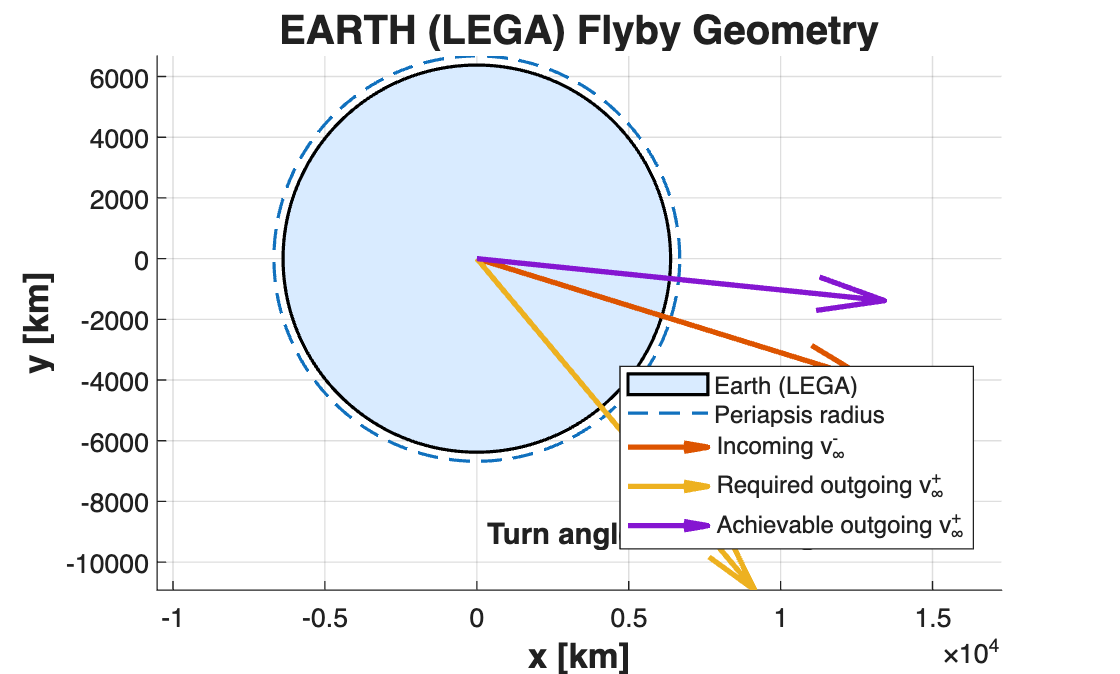

rpEarth = earth.radius + minAltMap.earth;
rpVenus = venus.radius + minAltMap.venus;

astro.plot.plotFlyby2D(traj.legs(1).vInfArr, traj.legs(2).vInfDep, earth.mu, rpEarth, +1, earth.radius, 'Earth (LEGA)');

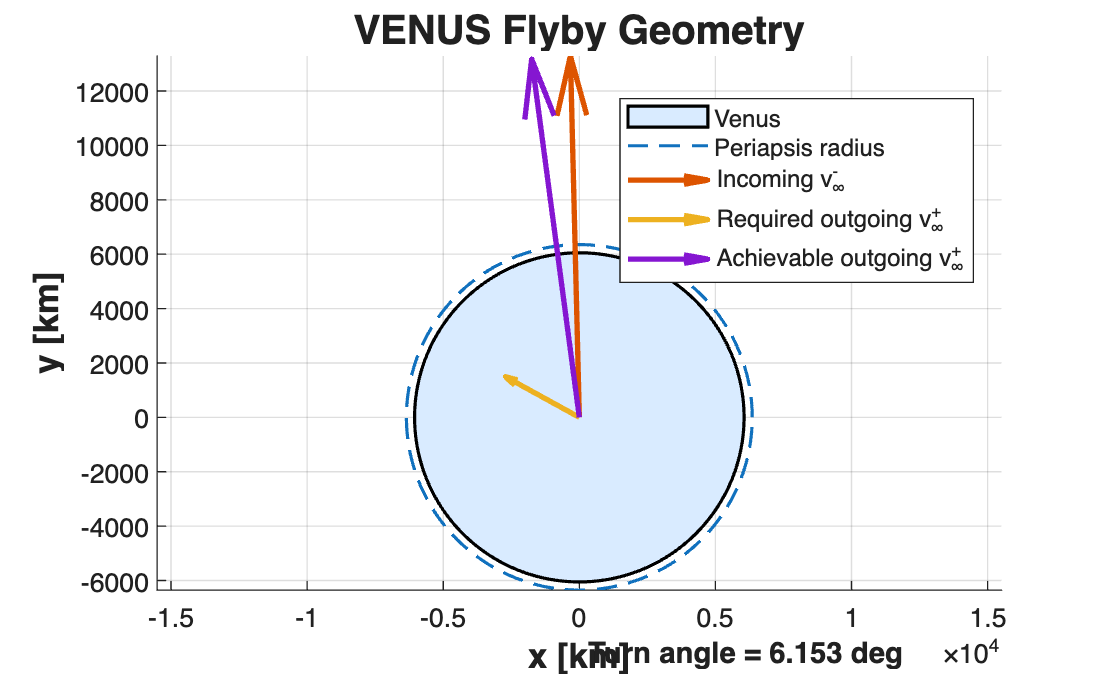

astro.plot.plotFlyby2D(traj.legs(2).vInfArr, traj.legs(3).vInfDep, venus.mu, rpVenus, +1, venus.radius, 'Venus');

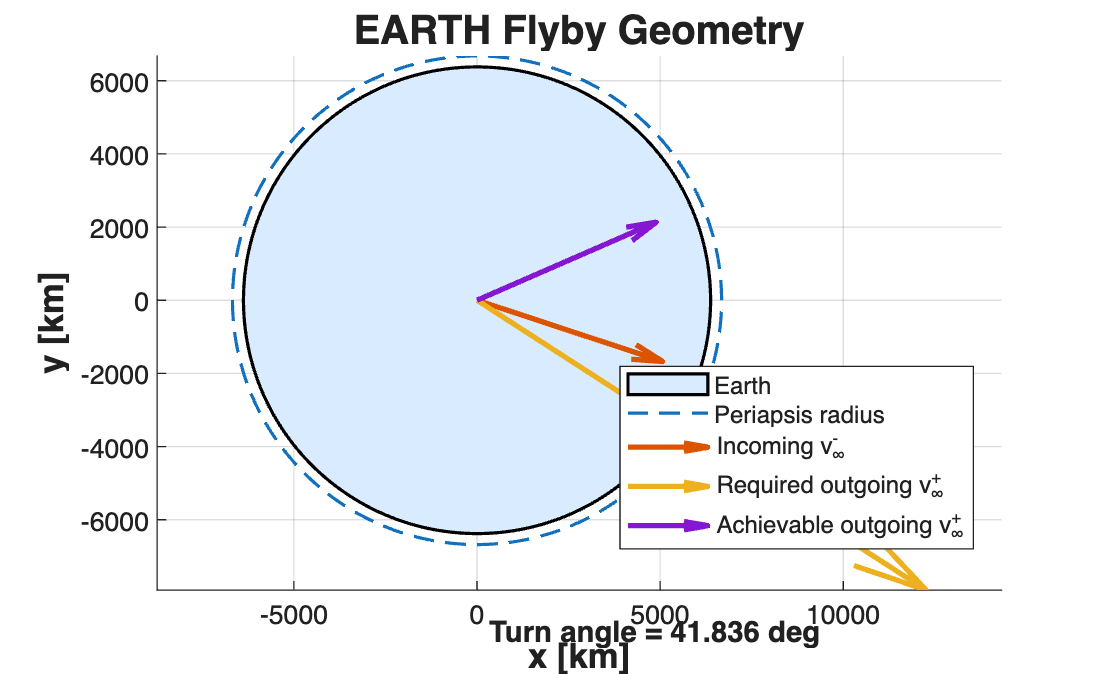

astro.plot.plotFlyby2D(traj.legs(3).vInfArr, traj.legs(4).vInfDep, earth.mu, rpEarth, +1, earth.radius, 'Earth');

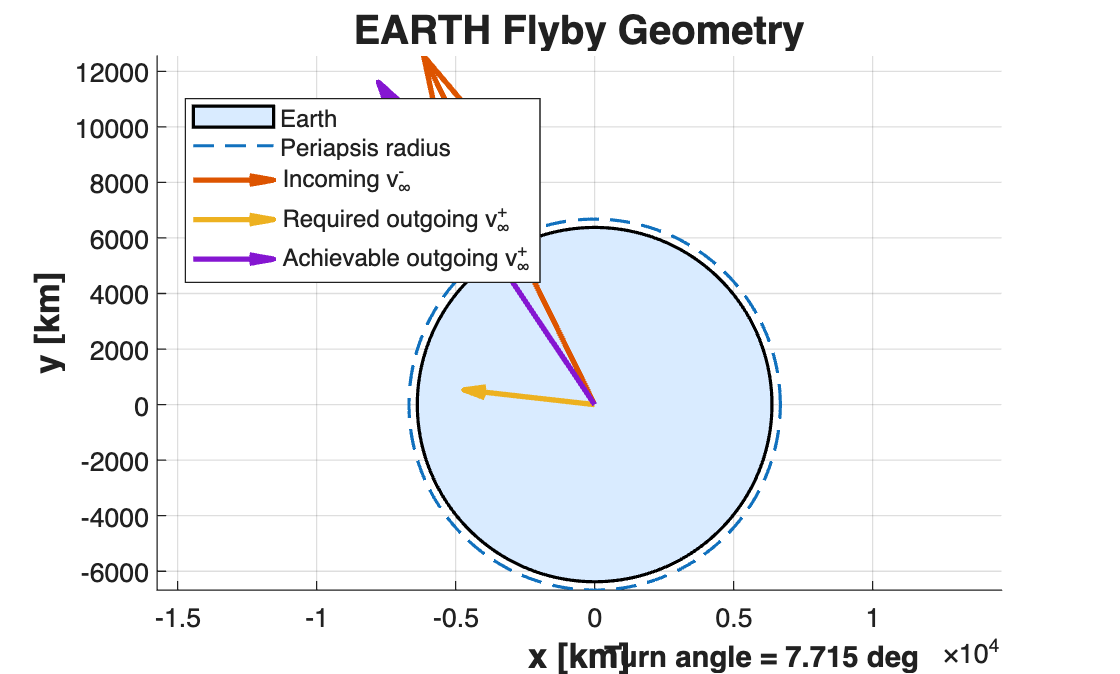

astro.plot.plotFlyby2D(traj.legs(4).vInfArr, traj.legs(5).vInfDep, earth.mu, rpEarth, +1, earth.radius, 'Earth');

## Build the reconstructed Lambert trajectory for plotting

rRecon = [];
optsProp = struct();
optsProp.RelTol = 1e-11;
optsProp.AbsTol = 1e-11;
optsProp.Solver = 'ode113';

for k = 1:numel(traj.legs)
    x0Leg = [traj.legs(k).r1; traj.legs(k).v1];
    tspan = [0, traj.legs(k).tofSec];

    outLeg = astro.propagators.propagate( ...
        @(t,x) astro.propagators.eomTwoBody(t, x, sun.mu), ...
        tspan, x0Leg, optsProp);

    rRecon = [rRecon; outLeg.x(:,1:3)]; %#ok<AGROW>
end

## SPICE truth comparison and heliocentric overview

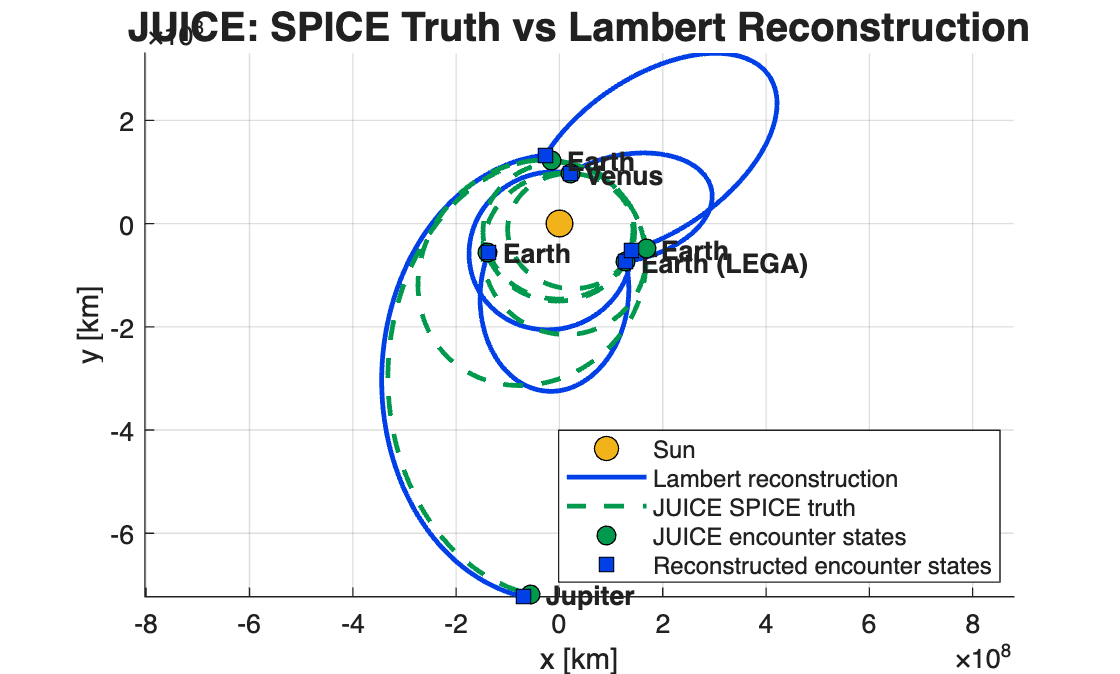

JUICE SPICE Truth Validation


Loading JUICE mission kernels from:
  /Users/gianlucamolinari/Desktop/astroToolbox/data/spice/juice


Loaded SPICE kernels from:
  /Users/gianlucamolinari/Desktop/astroToolbox/data/spice/juice
  TLS loaded : /Users/gianlucamolinari/Desktop/astroToolbox/data/spice/juice/kernels/lsk/naif0012.tls
  BSP count  : 26
  FK count   : 33
  PCK count  : 10
  CK count   : 77
  SCLK count : 2


Resolved JUICE spacecraft target as: JUICE


Sampling real JUICE trajectory from SPICE...



Encounter state comparison:


------------------------------------------------------------


2023-04-14 12:14:00  pos err =  2149093.605 km   vel err =  20.777576 km/s
2024-08-20 21:56:00  pos err =    15624.775 km   vel err =  16.492747 km/s
2025-08-31 00:00:00  pos err =   153763.907 km   vel err =  23.753512 km/s
2026-09-01 00:00:00  pos err = 27481580.595 km   vel err =   5.071769 km/s
2029-01-01 00:00:00  pos err = 16126416.831 km   vel err =  39.815544 km/s
2031-07-01 00:00:00  pos err = 14976605.294 km   vel err =   1.202067 km/s


juiceKernelDir = fullfile(kernelDir, 'juice');
hasJuiceDir = exist(juiceKernelDir, 'dir') == 7;

figure('Color','w');
hold on; axis equal; grid on;

hSun = plot(0, 0, 'o', ...
    'MarkerSize', 10, ...
    'MarkerFaceColor', clr.sun, ...
    'MarkerEdgeColor', 'k', ...
    'DisplayName', 'Sun');

astro.plot.plotOrbit2D(rRecon, 'Color', clr.recon, 'LineWidth', 1.8);
hRecon = plot(nan, nan, '-', 'Color', clr.recon, 'LineWidth', 1.8, ...
    'DisplayName', 'Lambert reconstruction');

xlabel('x [km]', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('y [km]', 'FontSize', 13, 'FontWeight', 'bold');

if hasJuiceDir
    fprintf('\n============================================================\n');
    fprintf('JUICE SPICE Truth Validation\n');
    fprintf('============================================================\n');
    fprintf('Loading JUICE mission kernels from:\n  %s\n', juiceKernelDir);

    try
        astro.ephem.loadSpiceKernels(juiceKernelDir);

        candidateTargets = {'JUICE', 'JUICE SPACECRAFT', '-28'};
        juiceTarget = '';
        testEpoch = dates{1};

        for k = 1:numel(candidateTargets)
            try
                tmp = astro.ephem.getSpiceState(candidateTargets{k}, testEpoch, 'SUN', 'J2000', 'NONE');
                juiceTarget = tmp.target;
                break
            catch
            end
        end

        if isempty(juiceTarget)
            error('Could not resolve JUICE target name automatically.');
        end

        fprintf('Resolved JUICE spacecraft target as: %s\n', juiceTarget);

        t0 = datetime(dates{1}, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
        tf = datetime(dates{end}, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
        nSamples = 1200;

        tHist = linspace(posixtime(t0), posixtime(tf), nSamples);
        tHist = datetime(tHist, 'ConvertFrom', 'posixtime');

        rJuice = zeros(nSamples, 3);

        fprintf('Sampling real JUICE trajectory from SPICE...\n');
        for k = 1:nSamples
            epochUTC = datestr(tHist(k), 'yyyy-mm-dd HH:MM:SS');
            sc = astro.ephem.getSpiceState(juiceTarget, epochUTC, 'SUN', 'J2000', 'NONE');
            rJuice(k,:) = sc.r(:).';
        end

        astro.plot.plotOrbit2D(rJuice, 'Color', clr.truth, 'LineStyle', '--', 'LineWidth', 1.8);
        hTruth = plot(nan, nan, '--', 'Color', clr.truth, 'LineWidth', 1.8, ...
            'DisplayName', 'JUICE SPICE truth');

        hTruthPts = plot(nan, nan, 'o', 'MarkerSize', 7, ...
            'MarkerFaceColor', clr.truth, 'MarkerEdgeColor', 'k', ...
            'DisplayName', 'JUICE encounter states');

        hReconPts = plot(nan, nan, 's', 'MarkerSize', 7, ...
            'MarkerFaceColor', clr.recon, 'MarkerEdgeColor', 'k', ...
            'DisplayName', 'Reconstructed encounter states');

        fprintf('\nEncounter state comparison:\n');
        fprintf('------------------------------------------------------------\n');

        for k = 1:numel(dates)
            epochUTC = dates{k};
            sc = astro.ephem.getSpiceState(juiceTarget, epochUTC, 'SUN', 'J2000', 'NONE');

            plot(sc.r(1), sc.r(2), 'o', ...
                'MarkerSize', 7, ...
                'MarkerFaceColor', clr.truth, ...
                'MarkerEdgeColor', 'k');

            if k == 1
                rRef = traj.legs(1).r1;
                vRef = traj.legs(1).v1;
            elseif k == numel(dates)
                rRef = traj.legs(end).r2;
                vRef = traj.legs(end).v2;
            else
                rRef = traj.legs(k-1).r2;
                vRef = traj.legs(k-1).v2;
            end

            plot(rRef(1), rRef(2), 's', ...
                'MarkerSize', 7, ...
                'MarkerFaceColor', clr.recon, ...
                'MarkerEdgeColor', 'k');

            text(sc.r(1), sc.r(2), ['  ' planetNames{k}], ...
                'FontSize', 10, 'FontWeight', 'bold', ...
                'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle');

            posErr = norm(sc.r - rRef);
            velErr = norm(sc.v - vRef);

            fprintf('%-19s  pos err = %12.3f km   vel err = %10.6f km/s\n', ...
                epochUTC, posErr, velErr);
        end

        title('JUICE: SPICE Truth vs Lambert Reconstruction', ...
            'FontSize', 15, 'FontWeight', 'bold');
        legend([hSun, hRecon, hTruth, hTruthPts, hReconPts], 'Location', 'best');

    catch ME
        fprintf('\nJUICE validation block failed.\nReason: %s\n', ME.message);

        hReconPts = plot(nan, nan, 's', 'MarkerSize', 7, ...
            'MarkerFaceColor', clr.recon, 'MarkerEdgeColor', 'k', ...
            'DisplayName', 'Encounter states');

        for k = 1:numel(traj.legs)
            plot(traj.legs(k).r1(1), traj.legs(k).r1(2), 's', ...
                'MarkerSize', 7, 'MarkerFaceColor', clr.recon, 'MarkerEdgeColor', 'k');
            plot(traj.legs(k).r2(1), traj.legs(k).r2(2), 's', ...
                'MarkerSize', 7, 'MarkerFaceColor', clr.recon, 'MarkerEdgeColor', 'k');
        end

        title('JUICE Reference Trajectory: Heliocentric Overview', ...
            'FontSize', 15, 'FontWeight', 'bold');
        legend([hSun, hRecon, hReconPts], 'Location', 'best');
    end
else
    fprintf('\nNo JUICE mission SPICE directory detected at:\n  %s\n', juiceKernelDir);
    fprintf('If you place ESA JUICE mission kernels there, the script will\n');
    fprintf('automatically compare reconstructed states against the spacecraft SPK.\n');

    hReconPts = plot(nan, nan, 's', 'MarkerSize', 7, ...
        'MarkerFaceColor', clr.recon, 'MarkerEdgeColor', 'k', ...
        'DisplayName', 'Encounter states');

    for k = 1:numel(traj.legs)
        plot(traj.legs(k).r1(1), traj.legs(k).r1(2), 's', ...
            'MarkerSize', 7, 'MarkerFaceColor', clr.recon, 'MarkerEdgeColor', 'k');
        plot(traj.legs(k).r2(1), traj.legs(k).r2(2), 's', ...
            'MarkerSize', 7, 'MarkerFaceColor', clr.recon, 'MarkerEdgeColor', 'k');
    end

    title('JUICE Reference Trajectory: Heliocentric Overview', ...
        'FontSize', 15, 'FontWeight', 'bold');
    legend([hSun, hRecon, hReconPts], 'Location', 'best');
end


fprintf('\nDone.\n');


Done.


## Future implementations

- Adding more interactive and polished plots/visualisations;

- Modelling Multigravity assists with deep space manouvers;

- Modelling low thrust manouvers;

- Automating $\Delta V$ and launch/arrival dates for transfers to planetary/small bodies;

- Validating against existing missions